# Online Directional Convolution

clear
close all

## Grid

grid = OctoGrid(2,2,2,100);

% add column
% grid.addBox(1.25,0.9,0,0.2,0.2,1.5)
% add wall
grid.addBox(0.6,0.8,0,0.8,0.1,1.5)

## Get Convolutional Kernel

kernel_size = 31;
sigma = 21;
kernel_x = directional_kernel_3d('x', kernel_size, sigma, kernel_size, sigma, kernel_size, sigma, 'gaussian');
kernel_y = directional_kernel_3d('y', kernel_size, sigma, kernel_size, sigma, kernel_size, sigma, 'gaussian');
kernel_z = directional_kernel_3d('z', kernel_size, sigma, kernel_size, sigma, kernel_size, sigma, 'gaussian');

## Check field in a straight line

If we look at a streight line away from the wall (normal on wall), it should be exponentially falling.

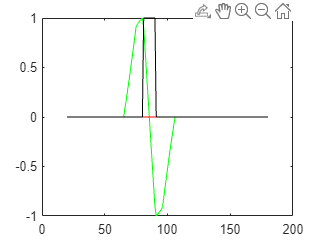

dx_list = [];
dy_list = [];
dz_list = [];

y_list = [];
ob_list = [];

x = 100;
z = 100;

for y = 20:1:180


    cutout = grid.grid(((1:kernel_size)+y-ceil(kernel_size/2)), ((1:kernel_size)+x-ceil(kernel_size/2)), ((1:kernel_size)+z-ceil(kernel_size/2)));

    C = cutout .* kernel_x; % Perform element-wise multiplication
    dx = sum(C(:)); % Sum all values  

    C = cutout .* kernel_y; % Perform element-wise multiplication
    dy = sum(C(:)); % Sum all values  

    C = cutout .* kernel_z; % Perform element-wise multiplication
    dz = sum(C(:)); % Sum all values  
    
    
    % list of dy values
    dy_list = [dy_list dy];

    % list of x coordinates
    dx_list = [dx_list dx];

    % list of z coordinates
    dz_list = [dz_list dz];

    % list of obstacle values
    ob_list = [ob_list grid.grid(y, x, z)];



    % list of y coordinates
    y_list = [y_list y];



end

figure()

plot(y_list,dx_list/max(dx_list+0.0001),'b')
hold on

plot(y_list,dy_list/max(dy_list+0.0001),'g')
plot(y_list,dz_list/max(dz_list+0.0001),'r')

plot(y_list, ob_list,'black')